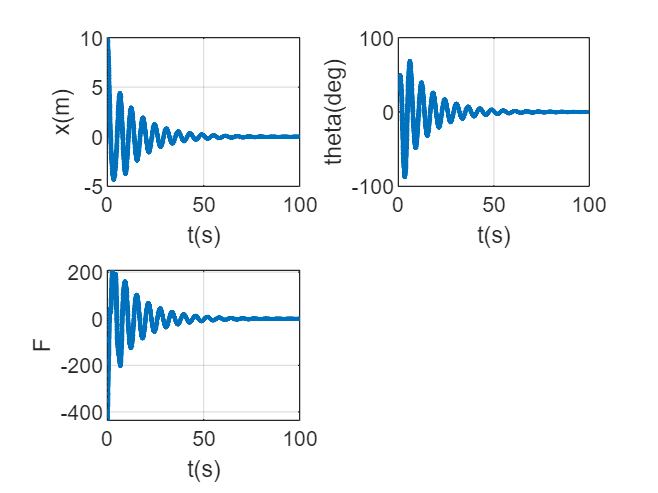

close all,clear,clc,
tic,
%% 参数设置
global m1 m2 l g
m1 = 20;
m2 = 10;
l = 5;
g = 9.8;

kp = 0.1;
kd = 1;

x = 10;
theta = 30/180*pi;
v = 0;
omega = 0;

state = [x;theta;v;omega];
stateout = state;

t0 = 0.0;
dt = 0.01;
tf = 100;
tout = t0:dt:tf;
Fout = [];
%% 仿真
for t = t0:dt:tf
    F = -m2*(g*cos(theta) + l*omega^2)*sin(theta) - kp*(m1 + ...
        m2*sin(theta)*sin(theta))*(m1*x - m2*l*sin(theta)) - ...
        kd*(m1*v - m2*l*omega*cos(theta));
    Fout = [Fout,F];

    ke1 = stateequation(t, state, F);
    ke2 = stateequation(t+0.5*dt, state+0.5*ke1*dt, F);
    ke3 = stateequation(t+0.5*dt, state+0.5*ke2*dt, F);
    ke4 = stateequation(t+dt, state+ke3*dt, F);
    state = state + 1/6*(ke1 + 2*ke2 + 2*ke3 + ke4)*dt;
    stateout = [stateout, state];

    x = state(1);
    theta = state(2);
    v = state(3);
    omega = state(4);
end

xout = stateout(1, :);
thetaout = stateout(2, :);
vout = stateout(3, :);
omegaout = stateout(4, :);

Fout = [Fout,Fout(end)];
tout = [tout,tout(end)+dt];
%% 绘图
figure;

subplot(2, 2, 1);
plot(tout, xout, 'LineWidth', 2);
xlabel('t(s)');ylabel('x(m)');
hold on;grid on;

subplot(2, 2, 2);
plot(tout, thetaout/pi*180, 'LineWidth', 2);
xlabel('t(s)');ylabel('theta(deg)');
hold on;grid on;

subplot(2, 2, 3);
plot(tout, Fout, 'LineWidth', 2);
xlabel('t(s)');ylabel('F');
hold on;grid on;

function statedot=stateequation(t, state, F)
global m1 m2 l g
%state = [x;theta;v;omega];
x = state(1);
theta = state(2);
v = state(3);
omega = state(4);

xdot = v;
thetadot = omega;
vdot = (F + m2*l*omega^2*sin(theta) + ...
       m2*g*sin(theta)*cos(theta))/(m1 + m2*sin(theta)*sin(theta));
omegadot = -(F*cos(theta) + m2*l*omega^2*sin(theta)*cos(theta) + ...
            (m1 + m2)*g*sin(theta))/(m1 + m2*sin(theta)*sin(theta))/l;

statedot = [xdot;thetadot;vdot;omegadot];
end